# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');
warning('off','all')

## **2.2 Position PID control**

− perfect steady–state tracking of step position references (hub side)

− perfect steady–state rejection of constant torque disturbances (hub side)

− step response (hub side) with settling time ts,5% ≤ 0.85 s and overshoot Mp ≤ 30%.

#### **Performace Specifications**

perf.ts5 = 0.85; 
perf.mp = 0.3;
perf.d = log(1/perf.mp)/sqrt(pi^2 + log(1/perf.mp)^2);
perf.wg = 3/(perf.d*perf.ts5);
perf.phi = atan(2*perf.d/(sqrt(sqrt(1+4*(perf.d^4))-2*(perf.d^2))))*rad2deg; % Used complete formula

Now we have to determine the transfer function from

% Simplified model: u -> thetah (34), p.7 of handout
s = tf('s');
Dp = Jeq*beam.Jb*s^3 + (Jeq*beam.Bb+beam.Jb*estimated.Beq)*s^2 + (estimated.Beq*beam.Bb + joint.k*(Jeq + beam.Jb/(gbox.N^2)))*s + joint.k*(estimated.Beq + beam.Bb/(gbox.N^2));
P = drv.dcgain*mot.Kt*(beam.Jb*s^2 + beam.Bb*s + joint.k)/((gbox.N*s)*((sens.curr.Rs+mot.R)*Dp + mot.Kt*mot.Ke*(beam.Jb*s^2 + beam.Bb*s + joint.k)))

P =
 
            6.429e-06 s^2 + 1.575e-05 s + 0.003859
  ----------------------------------------------------------
  2.357e-07 s^4 + 1.852e-06 s^3 + 0.0004051 s^2 + 0.001403 s
 
Continuous-time transfer function.



We explot Bode Method to determine PID parameters

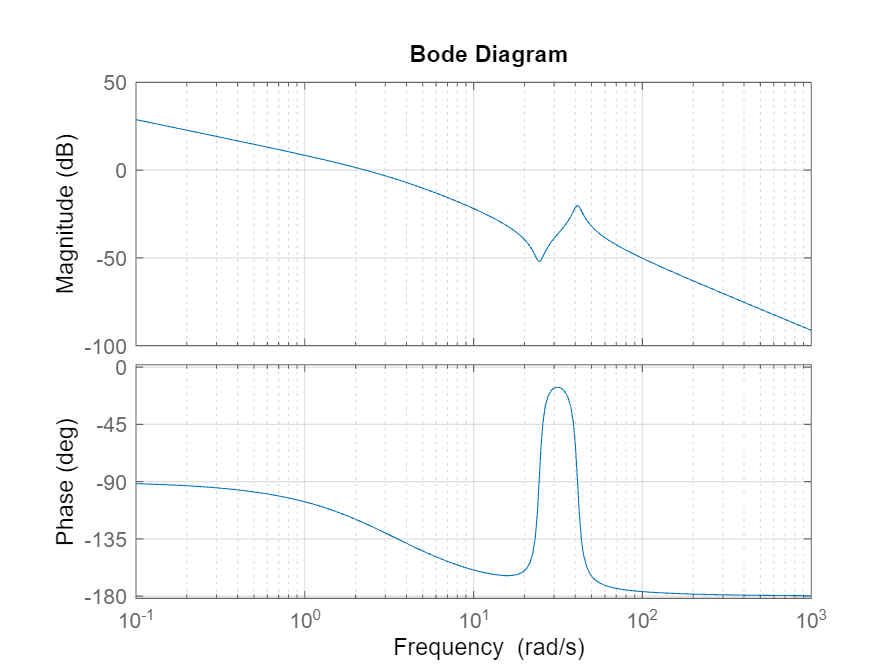

% Get magnitue and phase at the desired frequency
figure;
bode(P)
grid on

[magPwg, phasePwg] = bode(P, perf.wg)

magPwg = 0.0828

phasePwg = -159.2734

dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

pid.a = 20;                 
pid.K = dK * cos(dPh);
Td = (tan(dPh)+sqrt(tan(dPh)^2+4/pid.a))/(2*perf.wg);
Ti = pid.a*Td;

pid.Kd = pid.K*Td;
pid.Ki = pid.K/Ti;
disp(pid)

     a: 20
     K: 11.4589
    Kd: 0.5164
    Ki: 12.7141



Determine real derivative paramters for the PID

der.Tl = 1/(10*perf.wg);

Determine anti-windup parameters

awu.Tw = perf.ts5/5;
awu.Kw = 1/awu.Tw;

Simulations for the PID on the **BB **withouth AWU

awu.Kw = 0;
simul.stepdeg = 50;

# DO SIMULATION PID


%PID.BB.deg_50 = sim('PID_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');


PID.BB.deg_50.thh_est = thh_est;
PID.BB.deg_50.thd_est = thd_est;
PID.BB.deg_50.wh_est = wh_est;
PID.BB.deg_50.wh_est = wd_est;
PID.BB.deg_50.thh_ref = thh_ref;
PID.BB.deg_50.u = u;
PID.BB.deg_50.e = e;
PID.BB.deg_50.ia = ia;
PID.BB.deg_50.pid = pid;
PID.BB.deg_50.awu = awu;
PID.BB.deg_50.simul = simul;
PID.BB.deg_50.perf = perf;

stepinfo(PID.BB.deg_50.thh_est.signals.values,PID.BB.deg_50.thh_est.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1456
    TransientTime: 1.7779
     SettlingTime: 1.7779
      SettlingMin: 45.1800
      SettlingMax: 71.4600
        Overshoot: 42.9200
       Undershoot: 0
             Peak: 71.4600
         PeakTime: 1.3280


simul.stepdeg = 120;

# DO SIMULATION PID

%PID.BB.deg_120 = sim('PID_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
PID.BB.deg_120.thh_est = thh_est;
PID.BB.deg_120.thd_est = thd_est;
PID.BB.deg_120.wh_est = wh_est;
PID.BB.deg_120.wh_est = wd_est;
PID.BB.deg_120.thh_ref = thh_ref;
PID.BB.deg_120.u = u;
PID.BB.deg_120.e = e;
PID.BB.deg_120.ia = ia;
PID.BB.deg_120.pid = pid;
PID.BB.deg_120.awu = awu;
PID.BB.deg_120.simul = simul;
PID.BB.deg_120.perf = perf;

stepinfo(PID.BB.deg_120.thh_est.signals.values,PID.BB.deg_120.thh_est.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1724
    TransientTime: 2.2650
     SettlingTime: 2.2650
      SettlingMin: 108.5400
      SettlingMax: 172.9800
        Overshoot: 44.1500
       Undershoot: 0
             Peak: 172.9800
         PeakTime: 1.3810


Simulations for the PID on the **BB **with **AWU**

Determine anti-windup parameters

awu.Tw = perf.ts5/5;
awu.Kw = 1/awu.Tw;
%awu.Kw = 2; % manual tentative (with the given value you have too slow controller)

Simulations

simul.stepdeg = 50;

# DO SIMULATION PID

%PID.BB.deg_50AWU = sim('PID_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
PID.BB.deg_50AWU.thh_est = thh_est;
PID.BB.deg_50AWU.thd_est = thd_est;
PID.BB.deg_50AWU.wh_est = wh_est;
PID.BB.deg_50AWU.wh_est = wd_est;
PID.BB.deg_50AWU.thh_ref = thh_ref;
PID.BB.deg_50AWU.u = u;
PID.BB.deg_50AWU.e = e;
PID.BB.deg_50AWU.ia = ia;
PID.BB.deg_50AWU.pid = pid;
PID.BB.deg_50AWU.awu = awu;
PID.BB.deg_50AWU.simul = simul;
PID.BB.deg_50AWU.perf = perf;
stepinfo(PID.BB.deg_50AWU.thh_est.signals.values,PID.BB.deg_50AWU.thh_est.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1691
    TransientTime: 2.4589
     SettlingTime: 2.4589
      SettlingMin: 43.3800
      SettlingMax: 58.8600
        Overshoot: 17.7200
       Undershoot: 0
             Peak: 58.8600
         PeakTime: 1.3250


simul.stepdeg = 120;

# DO SIMULATION PID

%PID.BB.deg_120AWU = sim('PID_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
PID.BB.deg_120AWU.thh_est = thh_est;
PID.BB.deg_120AWU.thd_est = thd_est;
PID.BB.deg_120AWU.wh_est = wh_est;
PID.BB.deg_120AWU.wh_est = wd_est;
PID.BB.deg_120AWU.thh_ref = thh_ref;
PID.BB.deg_120AWU.u = u;
PID.BB.deg_120AWU.e = e;
PID.BB.deg_120AWU.ia = ia;
PID.BB.deg_120AWU.pid = pid;
PID.BB.deg_120AWU.awu = awu;
PID.BB.deg_120AWU.simul = simul;
PID.BB.deg_120AWU.perf = perf;

save('RES_01_PID.mat','PID');

stepinfo(PID.BB.deg_120AWU.thh_est.signals.values,PID.BB.deg_120AWU.thh_est.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.2152
    TransientTime: 2.5853
     SettlingTime: 2.5853
      SettlingMin: 94.5000
      SettlingMax: 127.2600
        Overshoot: 6.0500
       Undershoot: 0
             Peak: 127.2600
         PeakTime: 1.3570


Comparative figures

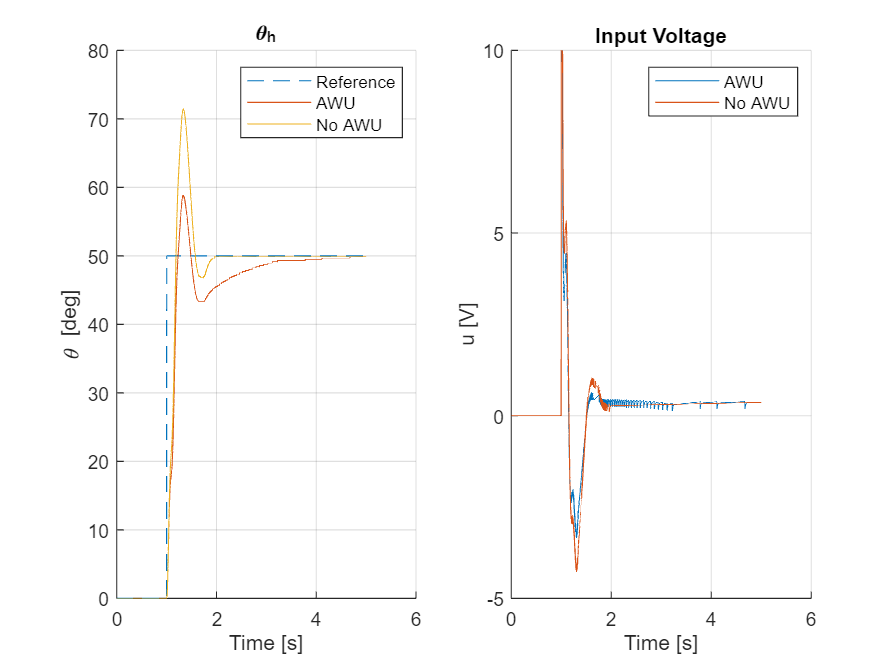

figure
subplot(1,2,1);
hold on;
plot(PID.BB.deg_50AWU.thh_ref.time, PID.BB.deg_50AWU.thh_ref.signals.values,'--');
plot(PID.BB.deg_50AWU.thh_est.time, PID.BB.deg_50AWU.thh_est.signals.values);
plot(PID.BB.deg_50.thh_est.time, PID.BB.deg_50.thh_est.signals.values);

legend('Reference', 'AWU', 'No AWU')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(PID.BB.deg_50AWU.u.time, PID.BB.deg_50AWU.u.signals.values);
plot(PID.BB.deg_50.u.time, PID.BB.deg_50.u.signals.values);
legend('AWU', 'No AWU')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

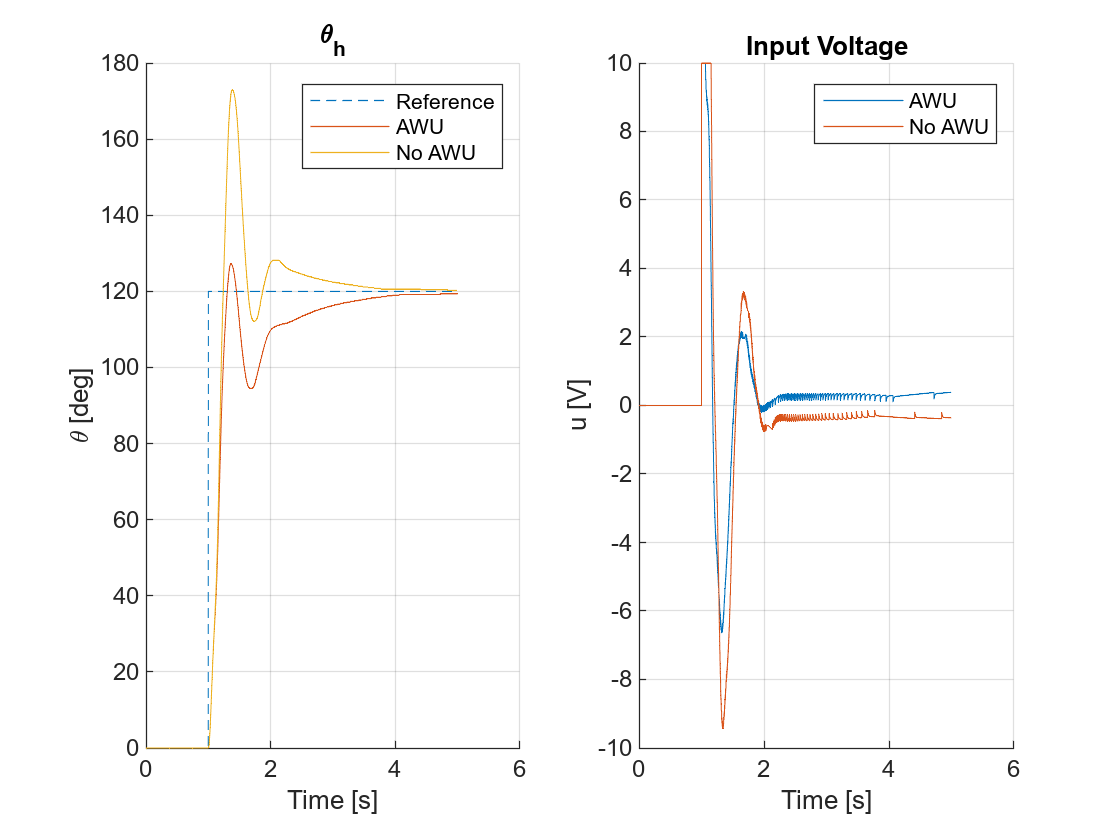

figure
subplot(1,2,1);
hold on;
plot(PID.BB.deg_120AWU.thh_ref.time, PID.BB.deg_120AWU.thh_ref.signals.values,'--');
plot(PID.BB.deg_120AWU.thh_est.time, PID.BB.deg_120AWU.thh_est.signals.values);
plot(PID.BB.deg_120.thh_est.time, PID.BB.deg_120.thh_est.signals.values);

legend('Reference', 'AWU', 'No AWU')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(PID.BB.deg_120AWU.u.time, PID.BB.deg_120AWU.u.signals.values);
plot(PID.BB.deg_120.u.time, PID.BB.deg_120.u.signals.values);
legend('AWU', 'No AWU')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

## **2.3 State space control**

For all the simulation in this part of the Lab we will need the same reference input

simul.stepdeg = 50;

#### **Performace Specifications**

perf.ts5 = 0.5; 
perf.mp = 0.3;
perf.d = log(1/perf.mp)/sqrt(pi^2 + log(1/perf.mp)^2);
perf.wg = 3/(perf.d*perf.ts5);

#### Nominal state space

ss_nominal.wn = perf.wg;
ss_nominal.d = perf.d;
ss_nominal.phi = atan(sqrt(1-ss_nominal.d^2)/perf.d);
ss_nominal.poles = -[exp(1i*ss_nominal.phi/2) exp(-1i*ss_nominal.phi/2) exp(1i*ss_nominal.phi) exp(-1i*ss_nominal.phi) ].*ss_nominal.wn;
%ss_nominal.poles =[-30-5*1i -30+5*1i -35-5*1i -35+5*1i]; % tuning?
ss_nominal.K = real(place(SS.A, SS.B, ss_nominal.poles));
ss_nominal.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
ss_nominal.Nx = ss_nominal.N(1:4);
ss_nominal.Nu = ss_nominal.N(5);

# DO SIMULATION SS NOMINAL

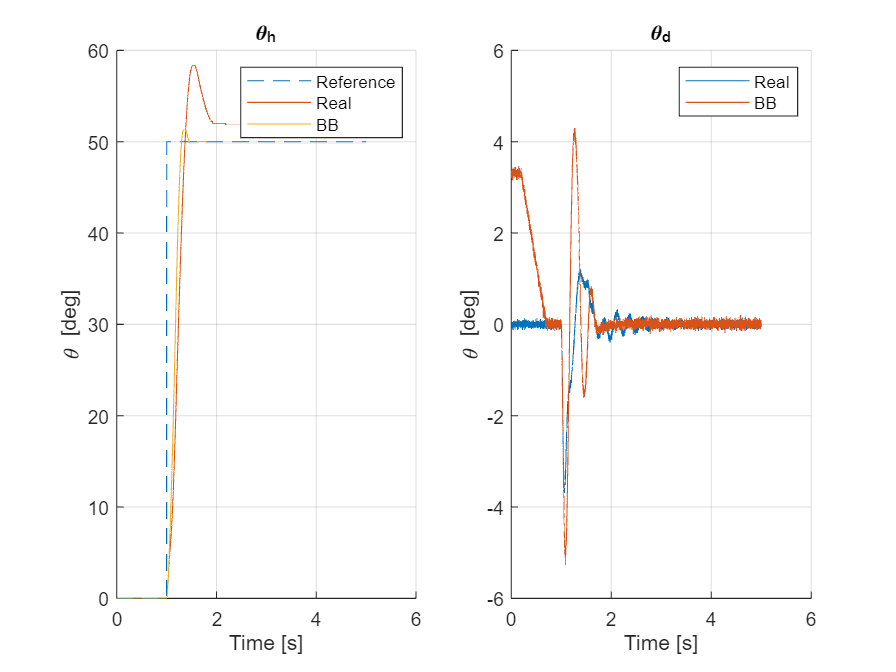


%ss_nominal.BB = sim('SS_Nominal_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ss_nominal.BB.thh_est = thh_est;
ss_nominal.BB.thd_est = thd_est;
ss_nominal.BB.wh_est = wh_est;
ss_nominal.BB.wh_est = wd_est;
ss_nominal.BB.thh_ref = thh_ref;
ss_nominal.BB.u = u;
ss_nominal.BB.ia = ia;
ss_nominal.BB.simul = simul;
ss_nominal.BB.perf = perf;
ss_nominal.BB.ss_nominal = ss_nominal;

save('RES_02_SS_NOMINAL.mat','ss_nominal');

figure
subplot(1,2,1);
hold on;
plot(ss_nominal.BB.thh_ref.time, ss_nominal.BB.thh_ref.signals.values,'--');
plot(ss_nominal.BB.thh_est.time, ss_nominal.BB.thh_est.signals.values);
legend('Reference', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(ss_nominal.real_model.thd_meas.time, ss_nominal.real_model.thd_meas.signals.values);
legend('BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')

#### Robust State Space

ss_robust.wn = perf.wg;
ss_robust.d = perf.d;
ss_robust.phi = atan(sqrt(1-ss_robust.d^2)/ss_robust.d);

ss_robust.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
ss_robust.Nx = ss_robust.N(1:4);
ss_robust.Nu = ss_robust.N(5);
ss_robust.Ae = [0 SS.C; zeros(4,1) SS.A];
ss_robust.Be = [0; SS.B];
ss_robust.Ce = [0 SS.C];

ss_robust.poles = -[exp(1i*ss_robust.phi/2) exp(-1i*ss_robust.phi/2) exp(1i*ss_robust.phi) exp(-1i*ss_robust.phi) 1].*ss_robust.wn;
%ss_robust.poles = [-25-5*1i -25+5*1i -30-5*1i -30+5*1i -25]; %tuning?
ss_robust.Ke = place(ss_robust.Ae, ss_robust.Be, ss_robust.poles);
ss_robust.Ki = ss_robust.Ke(1);
ss_robust.K = ss_robust.Ke(2:5);

# DO SIMULATION SS ROBUST

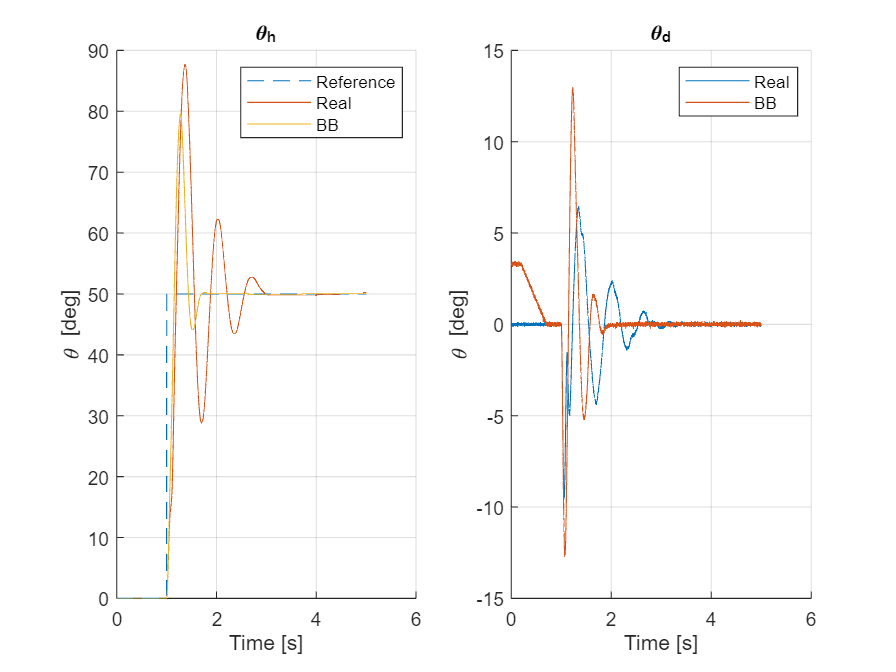

%ss_robust.BB = sim('SS_Robust_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

ss_robust.BB.thh_est = thh_est;
ss_robust.BB.thd_est = thd_est;
ss_robust.BB.wh_est = wh_est;
ss_robust.BB.wh_est = wd_est;
ss_robust.BB.thh_ref = thh_ref;
ss_robust.BB.u = u;
ss_robust.BB.ia = ia;
ss_robust.BB.simul = simul;
ss_robust.BB.perf = perf;
ss_robust.BB.ss_robust = ss_robust;

save('RES_03_SS_ROBUST.mat','ss_robust');

figure
subplot(1,2,1);
hold on;
plot(ss_robust.real_model.thh_ref.time, ss_robust.real_model.thh_ref.signals.values,'--');
plot(ss_robust.BB.thh_est.time, ss_robust.BB.thh_est.signals.values);
legend('Reference', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(ss_robust.BB.thd_est.time, ss_robust.BB.thd_est.signals.values);
legend('BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')

## 2.4 LQR

simul.stepdeg = 50;

#### Nominal LQR

lqr_nominal.wn = perf.wg;
lqr_nominal.d = perf.d;
lqr_nominal.phi = atan(sqrt(1-lqr_nominal.d^2)/perf.d);
lqr_nominal.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_nominal.Nx = lqr_nominal.N(1:4);
lqr_nominal.Nu = lqr_nominal.N(5);

lqr_nominal.sysG = ss(SS.A, SS.B, SS.C, SS.D);
lqr_nominal.sysGp = ss(-SS.A, -SS.B, SS.C, SS.D);

lqr_nominal.sigma_min = -3/perf.ts5;
lqr_nominal.phi = atan(sqrt(1-perf.d^2)/perf.d)+pi/2;% added pi/2 to make it work like in the assignment
lqr_nominal.r = 0.00027; % design choice to obtain oll the sbable roots inside the allowed area
%lqr_nominal.r = 0.00045; % testing

lqr_nominal.K = lqry(lqr_nominal.sysG, 1, lqr_nominal.r);

Plotting symmetric root locus

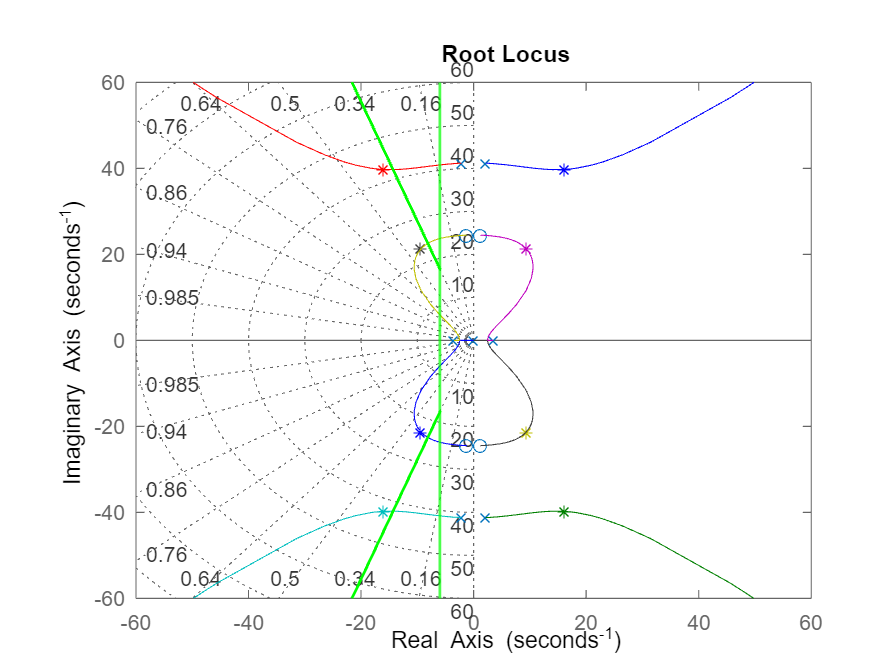

figure
hold on
rlocus(lqr_nominal.sysG*lqr_nominal.sysGp, 1/lqr_nominal.r, '*') % '*' marks the current position of poles for given r
rlocus(lqr_nominal.sysG*lqr_nominal.sysGp)                       % plots the full
xline(lqr_nominal.sigma_min, "Color", "green", LineWidth=1.3)
x=-10000:0.1:lqr_nominal.sigma_min+0.1;
plot(x, lqr_nominal.phi*x, "Color", "green", LineWidth=1.3)
plot(x, -lqr_nominal.phi*x, "Color", "green", LineWidth=1.3)
grid on
xlim([-60 60])
ylim([-60 60])

%this part has been added to use only a simulation file for multiple tests

ss_nominal.K = lqr_nominal.K;
ss_nominal.Nx = lqr_nominal.Nx;
ss_nominal.Nu = lqr_nominal.Nu;

# DO SIMULATION SS NOMINAL

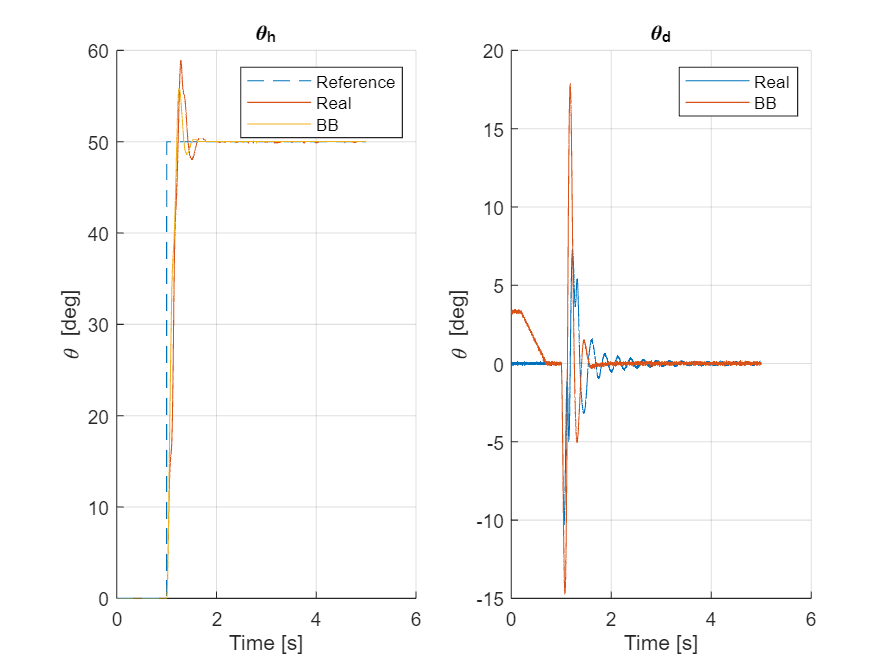


%lqr_nominal.BB = sim('SS_Nominal_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

lqr_nominal.BB.thh_est = thh_est;
lqr_nominal.BB.thd_est = thd_est;
lqr_nominal.BB.wh_est = wh_est;
lqr_nominal.BB.wh_est = wd_est;
lqr_nominal.BB.thh_ref = thh_ref;
lqr_nominal.BB.u = u;
lqr_nominal.BB.ia = ia;
lqr_nominal.BB.simul = simul;
lqr_nominal.BB.perf = perf;
lqr_nominal.BB.lqr_nominal = lqr_nominal;

save('RES_04_LQR_NOMINAL.mat','lqr_nominal');

figure
subplot(1,2,1);
hold on;
plot(lqr_nominal.real_model.thh_meas.time, lqr_nominal.real_model.thh_meas.signals.values);
plot(lqr_nominal.BB.thh_est.time, lqr_nominal.BB.thh_est.signals.values);
legend('Reference',  'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(lqr_nominal.BB.thd_est.time, lqr_nominal.BB.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')


stepinfo(lqr_nominal.real_model.thh_meas.signals.values, lqr_nominal.real_model.thh_meas.time, simul.stepdeg, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1751
    TransientTime: 1.3963
     SettlingTime: 1.3963
      SettlingMin: 45.1800
      SettlingMax: 58.8600
        Overshoot: 17.7200
       Undershoot: 0
             Peak: 58.8600
         PeakTime: 1.2800


#### Nominal Bryson's rule LQR

lqr_nominal_bryson.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_nominal_bryson.Nx = lqr_nominal_bryson.N(1:4);
lqr_nominal_bryson.Nu = lqr_nominal_bryson.N(5);
lqr_nominal_bryson.sysP = ss(SS.A, SS.B, SS.C, SS.D);



lqr_nominal_bryson.thh_bar = 0.3*simul.stepdeg*pi/180;
lqr_nominal_bryson.thd_bar = pi/36;
lqr_nominal_bryson.u_bar = 10;
lqr_nominal_bryson.Q = diag([1/lqr_nominal_bryson.thh_bar^2   1/lqr_nominal_bryson.thd_bar^2  0  0]);
lqr_nominal_bryson.r = 1/lqr_nominal_bryson.u_bar^2;
lqr_nominal_bryson.K = lqr(lqr_nominal_bryson.sysP, lqr_nominal_bryson.Q, lqr_nominal_bryson.r);


%this part has been added to use only a simulation file for multiple tests
ss_nominal.K =  lqr_nominal_bryson.K;
ss_nominal.Nx = lqr_nominal_bryson.Nx;
ss_nominal.Nu = lqr_nominal_bryson.Nu;

# DO SIMULATION SS NOMINAL

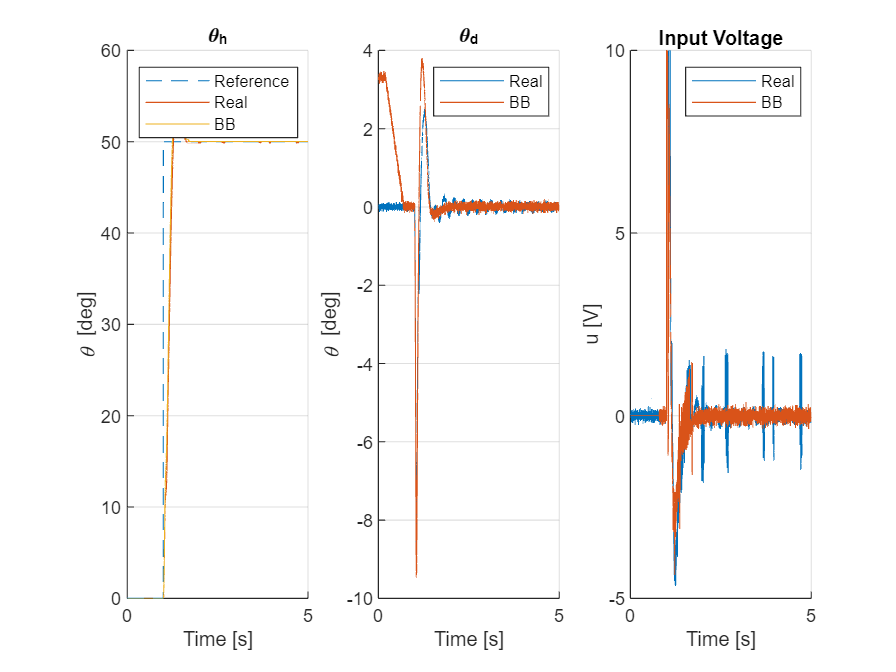

%lqr_nominal_bryson.BB = sim('SS_Nominal_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
lqr_nominal_bryson.BB.thh_est = thh_est;
lqr_nominal_bryson.BB.thd_est = thd_est;
lqr_nominal_bryson.BB.wh_est = wh_est;
lqr_nominal_bryson.BB.wh_est = wd_est;
lqr_nominal_bryson.BB.thh_ref = thh_ref;
lqr_nominal_bryson.BB.u = u;
lqr_nominal_bryson.BB.ia = ia;
lqr_nominal_bryson.BB.simul = simul;
lqr_nominal_bryson.BB.perf = perf;
lqr_nominal_bryson.BB.lqr_nominal_bryson = lqr_nominal_bryson;

save('RES_04_lqr_nominal_bryson.mat','lqr_nominal_bryson');


figure
subplot(1,3,1);
hold on;
plot(lqr_nominal_bryson.real_model.thh_ref.time, lqr_nominal_bryson.real_model.thh_ref.signals.values,'--');
plot(lqr_nominal_bryson.BB.thh_est.time, lqr_nominal_bryson.BB.thh_est.signals.values);
legend('Reference', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_nominal_bryson.BB.thd_est.time, lqr_nominal_bryson.BB.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_nominal_bryson.BB.u.time, lqr_nominal_bryson.BB.u.signals.values);
legend('BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

stepinfo(lqr_nominal_bryson.real_model.thh_meas.signals.values, lqr_nominal_bryson.real_model.thh_meas.time, simul.stepdeg, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.2131
    TransientTime: 1.4863
     SettlingTime: 1.4863
      SettlingMin: 45.1800
      SettlingMax: 54.3600
        Overshoot: 8.7200
       Undershoot: 0
             Peak: 54.3600
         PeakTime: 1.3630


#### Robust LQR

lqr_robust.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_robust.Nx = lqr_robust.N(1:4);
lqr_robust.Nu = lqr_robust.N(5);
lqr_robust.Ae = [0 SS.C; zeros(4,1) SS.A];
lqr_robust.Be = [0; SS.B];
lqr_robust.Ce = [1 0 0 0 0];

% NOTE: SYSTEM IS NOT CONTROLLABLE
lqr_robust.sysG = ss(lqr_robust.Ae, lqr_robust.Be, lqr_robust.Ce, SS.D);
lqr_robust.sysGp = ss(-lqr_robust.Ae, -lqr_robust.Be, lqr_robust.Ce, SS.D);

lqr_robust.sigma_min = -3/perf.ts5;
lqr_robust.phi = atan(sqrt(1-perf.d^2)/perf.d)+pi/2;% added pi/2 to make it work like in the assignment
lqr_robust.r = 0.000013; % design choice to obtain all the low frequency sbable roots barely inside the allowed area

lqr_robust.Ke = lqry(lqr_robust.sysG, 1, lqr_robust.r);

Plotting symmetric root locus

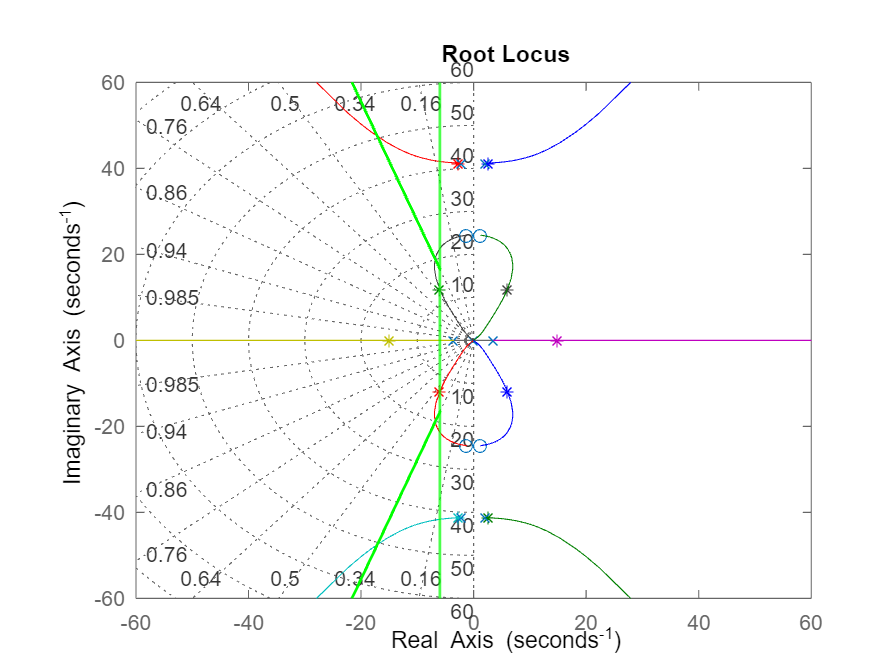

figure
hold on
rlocus(lqr_robust.sysG*lqr_robust.sysGp,1/lqr_robust.r, '*') % choice of r
rlocus(lqr_robust.sysG*lqr_robust.sysGp);                    % whole root locus
xline(lqr_robust.sigma_min, "Color", "green", LineWidth=1.3)
x=-10000:0.1:lqr_robust.sigma_min+0.1;
plot(x, lqr_robust.phi*x, "Color", "green", LineWidth=1.3)
plot(x, -lqr_robust.phi*x, "Color", "green", LineWidth=1.3)
grid on
xlim([-60 60])
ylim([-60 60])

lqr_robust.Ki = lqr_robust.Ke(1);
lqr_robust.K = lqr_robust.Ke(2:5);

%this part has been added to use only a simulation file for multiple tests
ss_robust.K =  lqr_robust.K;
ss_robust.Nx = lqr_robust.Nx;
ss_robust.Nu = lqr_robust.Nu;
ss_robust.Ki =  lqr_robust.Ki;


# DO SIMULATION SS ROBUST

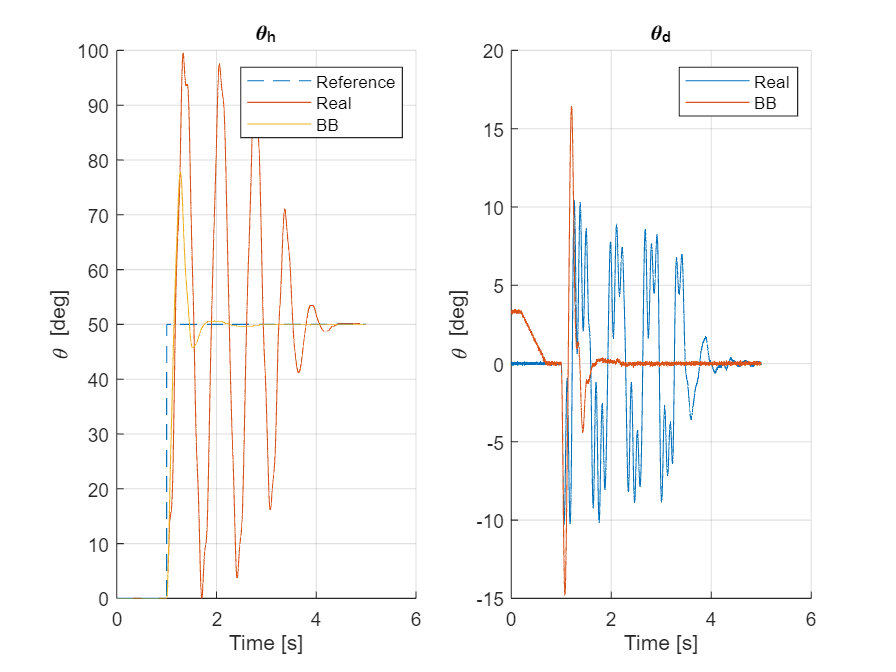


%lqr_robust.BB = sim('SS_Robust_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
lqr_robust.BB.thh_est = thh_est;
lqr_robust.BB.thd_est = thd_est;
lqr_robust.BB.wh_est = wh_est;
lqr_robust.BB.wh_est = wd_est;
lqr_robust.BB.thh_ref = thh_ref;
lqr_robust.BB.u = u;
lqr_robust.BB.ia = ia;
lqr_robust.BB.simul = simul;
lqr_robust.BB.perf = perf;
lqr_robust.BB.lqr_robust = lqr_robust;

save('RES_05_lqr_robust.mat','lqr_robust');


figure
subplot(1,2,1);
hold on;
plot(lqr_robust.real_model.thh_ref.time, lqr_robust.real_model.thh_ref.signals.values,'--');
plot(lqr_robust.BB.thh_est.time, lqr_robust.BB.thh_est.signals.values);
legend('Reference', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(lqr_robust.BB.thd_est.time, lqr_robust.BB.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')

#### Robust Bryson's rule LQR test q11 1

lqr_robust_bryson.q11_selector = 1;

lqr_robust_bryson.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_robust_bryson.Nx = lqr_robust_bryson.N(1:4);
lqr_robust_bryson.Nu = lqr_robust_bryson.N(5);
lqr_robust_bryson.Ae = [0 SS.C; zeros(4,1) SS.A];
lqr_robust_bryson.Be = [0; SS.B];
lqr_robust_bryson.Ce = [1 0 0 0 0];
lqr_robust_bryson.sysP = ss(lqr_robust_bryson.Ae, lqr_robust_bryson.Be, lqr_robust_bryson.Ce, SS.D);

lqr_robust_bryson.thh_bar = 0.3*simul.stepdeg*pi/180;
lqr_robust_bryson.thd_bar = pi/36;
lqr_robust_bryson.u_bar = 10;
lqr_robust_bryson.q_11 = [1e-2 1e-1 1 10 100]; %higher value faster to reach asymptotic tracking but bigger overshoot
                                                % best probably 100 because it respect all specs required
lqr_robust_bryson.Q = diag([lqr_robust_bryson.q_11(5) 1/lqr_robust_bryson.thh_bar^2   1/lqr_robust_bryson.thd_bar^2  0  0]);
lqr_robust_bryson.r = 1/lqr_robust_bryson.u_bar^2;
lqr_robust_bryson.Ke = lqr(lqr_robust_bryson.sysP, lqr_robust_bryson.Q, lqr_robust_bryson.r);
lqr_robust_bryson.Ki = lqr_robust_bryson.Ke(1);
lqr_robust_bryson.K = lqr_robust_bryson.Ke(2:5);

%this part has been added to use only a simulation file for multiple tests
ss_robust.K =  lqr_robust_bryson.K;
ss_robust.Ki =  lqr_robust_bryson.Ki;
ss_robust.Nx = lqr_robust_bryson.Nx;
ss_robust.Nu = lqr_robust_bryson.Nu;


# DO SIMULATION SS ROBUST

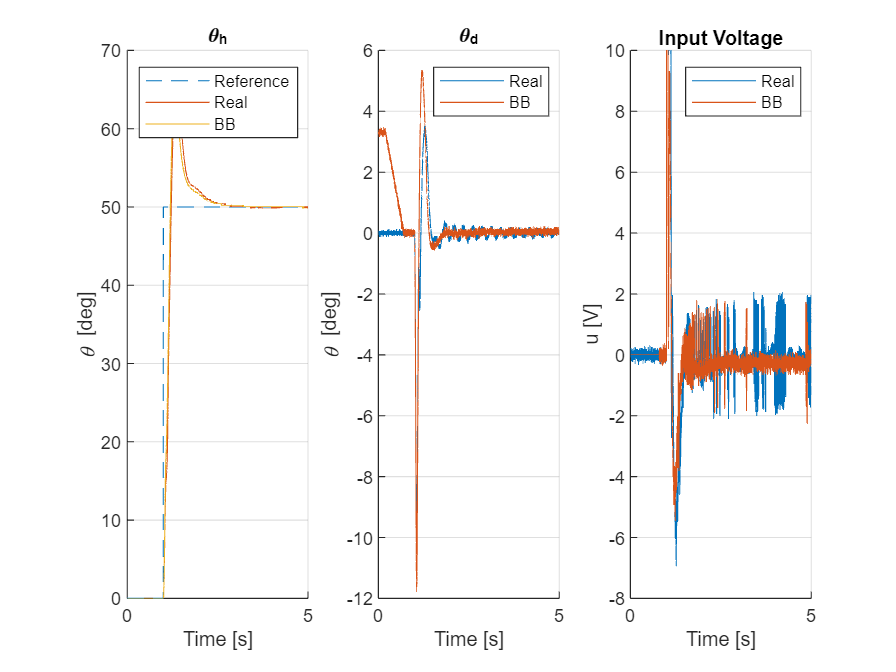

%lqr_robust_bryson.BB = sim('SS_Robust_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

lqr_robust_bryson.BB.q11_1.thh_est = thh_est;
lqr_robust_bryson.BB.q11_1.thd_est = thd_est;
lqr_robust_bryson.BB.q11_1.wh_est = wh_est;
lqr_robust_bryson.BB.q11_1.wh_est = wd_est;
lqr_robust_bryson.BB.q11_1.thh_ref = thh_ref;
lqr_robust_bryson.BB.q11_1.u = u;
lqr_robust_bryson.BB.q11_1.ia = ia;
lqr_robust_bryson.BB.q11_1.simul = simul;
lqr_robust_bryson.BB.q11_1.perf = perf;
lqr_robust_bryson.BB.q11_1.lqr_robust_bryson = lqr_robust_bryson;



figure
subplot(1,3,1);
hold on;
plot(lqr_robust_bryson.BB.q11_1.thh_ref.time, lqr_robust_bryson.BB.q11_1.thh_ref.signals.values,'--');
plot(lqr_robust_bryson.BB.q11_1.thh_est.time, lqr_robust_bryson.BB.q11_1.thh_est.signals.values);
legend('Reference',  'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_robust_bryson.BB.q11_1.thd_est.time, lqr_robust_bryson.BB.q11_1.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_robust_bryson.BB.q11_1.u.time, lqr_robust_bryson.BB.q11_1.u.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

#### Robust Bryson's rule LQR test q11 2

lqr_robust_bryson.q11_selector = 2;

lqr_robust_bryson.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_robust_bryson.Nx = lqr_robust_bryson.N(1:4);
lqr_robust_bryson.Nu = lqr_robust_bryson.N(5);
lqr_robust_bryson.Ae = [0 SS.C; zeros(4,1) SS.A];
lqr_robust_bryson.Be = [0; SS.B];
lqr_robust_bryson.Ce = [1 0 0 0 0];
lqr_robust_bryson.sysP = ss(lqr_robust_bryson.Ae, lqr_robust_bryson.Be, lqr_robust_bryson.Ce, SS.D);

lqr_robust_bryson.thh_bar = 0.3*simul.stepdeg*pi/180;
lqr_robust_bryson.thd_bar = pi/36;
lqr_robust_bryson.u_bar = 10;
lqr_robust_bryson.q_11 = [1e-2 1e-1 1 10 100]; %higher value faster to reach asymptotic tracking but bigger overshoot
                                                % best probably 100 because it respect all specs required
lqr_robust_bryson.Q = diag([lqr_robust_bryson.q_11(5) 1/lqr_robust_bryson.thh_bar^2   1/lqr_robust_bryson.thd_bar^2  0  0]);
lqr_robust_bryson.r = 1/lqr_robust_bryson.u_bar^2;
lqr_robust_bryson.Ke = lqr(lqr_robust_bryson.sysP, lqr_robust_bryson.Q, lqr_robust_bryson.r);
lqr_robust_bryson.Ki = lqr_robust_bryson.Ke(1);
lqr_robust_bryson.K = lqr_robust_bryson.Ke(2:5);

%this part has been added to use only a simulation file for multiple tests
ss_robust.K =  lqr_robust_bryson.K;
ss_robust.Ki =  lqr_robust_bryson.Ki;
ss_robust.Nx = lqr_robust_bryson.Nx;
ss_robust.Nu = lqr_robust_bryson.Nu;


# DO SIMULATION SS ROBUST

%lqr_robust_bryson.BB = sim('SS_Robust_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

lqr_robust_bryson.BB.q11_2.thh_est = thh_est;
lqr_robust_bryson.BB.q11_2.thd_est = thd_est;
lqr_robust_bryson.BB.q11_2.wh_est = wh_est;
lqr_robust_bryson.BB.q11_2.wh_est = wd_est;
lqr_robust_bryson.BB.q11_2.thh_ref = thh_ref;
lqr_robust_bryson.BB.q11_2.u = u;
lqr_robust_bryson.BB.q11_2.ia = ia;
lqr_robust_bryson.BB.q11_2.simul = simul;
lqr_robust_bryson.BB.q11_2.perf = perf;
lqr_robust_bryson.BB.q11_2.lqr_robust_bryson = lqr_robust_bryson;



figure
subplot(1,3,1);
hold on;
plot(lqr_robust_bryson.BB.q11_2.thh_ref.time, lqr_robust_bryson.BB.q11_2.thh_ref.signals.values,'--');
plot(lqr_robust_bryson.BB.q11_2.thh_est.time, lqr_robust_bryson.BB.q11_2.thh_est.signals.values);
legend('Reference',  'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_robust_bryson.BB.q11_2.thd_est.time, lqr_robust_bryson.BB.q11_2.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_robust_bryson.BB.q11_2.u.time, lqr_robust_bryson.BB.q11_2.u.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

#### Robust Bryson's rule LQR test q11 3

lqr_robust_bryson.q11_selector = 3;

lqr_robust_bryson.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_robust_bryson.Nx = lqr_robust_bryson.N(1:4);
lqr_robust_bryson.Nu = lqr_robust_bryson.N(5);
lqr_robust_bryson.Ae = [0 SS.C; zeros(4,1) SS.A];
lqr_robust_bryson.Be = [0; SS.B];
lqr_robust_bryson.Ce = [1 0 0 0 0];
lqr_robust_bryson.sysP = ss(lqr_robust_bryson.Ae, lqr_robust_bryson.Be, lqr_robust_bryson.Ce, SS.D);

lqr_robust_bryson.thh_bar = 0.3*simul.stepdeg*pi/180;
lqr_robust_bryson.thd_bar = pi/36;
lqr_robust_bryson.u_bar = 10;
lqr_robust_bryson.q_11 = [1e-2 1e-1 1 10 100]; %higher value faster to reach asymptotic tracking but bigger overshoot
                                                % best probably 100 because it respect all specs required
lqr_robust_bryson.Q = diag([lqr_robust_bryson.q_11(5) 1/lqr_robust_bryson.thh_bar^2   1/lqr_robust_bryson.thd_bar^2  0  0]);
lqr_robust_bryson.r = 1/lqr_robust_bryson.u_bar^2;
lqr_robust_bryson.Ke = lqr(lqr_robust_bryson.sysP, lqr_robust_bryson.Q, lqr_robust_bryson.r);
lqr_robust_bryson.Ki = lqr_robust_bryson.Ke(1);
lqr_robust_bryson.K = lqr_robust_bryson.Ke(2:5);

%this part has been added to use only a simulation file for multiple tests
ss_robust.K =  lqr_robust_bryson.K;
ss_robust.Ki =  lqr_robust_bryson.Ki;
ss_robust.Nx = lqr_robust_bryson.Nx;
ss_robust.Nu = lqr_robust_bryson.Nu;


# DO SIMULATION SS ROBUST

%lqr_robust_bryson.BB = sim('SS_Robust_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

lqr_robust_bryson.BB.q11_3.thh_est = thh_est;
lqr_robust_bryson.BB.q11_3.thd_est = thd_est;
lqr_robust_bryson.BB.q11_3.wh_est = wh_est;
lqr_robust_bryson.BB.q11_3.wh_est = wd_est;
lqr_robust_bryson.BB.q11_3.thh_ref = thh_ref;
lqr_robust_bryson.BB.q11_3.u = u;
lqr_robust_bryson.BB.q11_3.ia = ia;
lqr_robust_bryson.BB.q11_3.simul = simul;
lqr_robust_bryson.BB.q11_3.perf = perf;
lqr_robust_bryson.BB.q11_3.lqr_robust_bryson = lqr_robust_bryson;



figure
subplot(1,3,1);
hold on;
plot(lqr_robust_bryson.BB.q11_3.thh_ref.time, lqr_robust_bryson.BB.q11_3.thh_ref.signals.values,'--');
plot(lqr_robust_bryson.BB.q11_3.thh_est.time, lqr_robust_bryson.BB.q11_3.thh_est.signals.values);
legend('Reference',  'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_robust_bryson.BB.q11_3.thd_est.time, lqr_robust_bryson.BB.q11_3.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_robust_bryson.BB.q11_3.u.time, lqr_robust_bryson.BB.q11_3.u.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')


#### Robust Bryson's rule LQR test q11 4

lqr_robust_bryson.q11_selector = 4;

lqr_robust_bryson.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_robust_bryson.Nx = lqr_robust_bryson.N(1:4);
lqr_robust_bryson.Nu = lqr_robust_bryson.N(5);
lqr_robust_bryson.Ae = [0 SS.C; zeros(4,1) SS.A];
lqr_robust_bryson.Be = [0; SS.B];
lqr_robust_bryson.Ce = [1 0 0 0 0];
lqr_robust_bryson.sysP = ss(lqr_robust_bryson.Ae, lqr_robust_bryson.Be, lqr_robust_bryson.Ce, SS.D);

lqr_robust_bryson.thh_bar = 0.3*simul.stepdeg*pi/180;
lqr_robust_bryson.thd_bar = pi/36;
lqr_robust_bryson.u_bar = 10;
lqr_robust_bryson.q_11 = [1e-2 1e-1 1 10 100]; %higher value faster to reach asymptotic tracking but bigger overshoot
                                                % best probably 100 because it respect all specs required
lqr_robust_bryson.Q = diag([lqr_robust_bryson.q_11(5) 1/lqr_robust_bryson.thh_bar^2   1/lqr_robust_bryson.thd_bar^2  0  0]);
lqr_robust_bryson.r = 1/lqr_robust_bryson.u_bar^2;
lqr_robust_bryson.Ke = lqr(lqr_robust_bryson.sysP, lqr_robust_bryson.Q, lqr_robust_bryson.r);
lqr_robust_bryson.Ki = lqr_robust_bryson.Ke(1);
lqr_robust_bryson.K = lqr_robust_bryson.Ke(2:5);

%this part has been added to use only a simulation file for multiple tests
ss_robust.K =  lqr_robust_bryson.K;
ss_robust.Ki =  lqr_robust_bryson.Ki;
ss_robust.Nx = lqr_robust_bryson.Nx;
ss_robust.Nu = lqr_robust_bryson.Nu;


# DO SIMULATION SS ROBUST

%lqr_robust_bryson.BB = sim('SS_Robust_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

lqr_robust_bryson.BB.q11_4.thh_est = thh_est;
lqr_robust_bryson.BB.q11_4.thd_est = thd_est;
lqr_robust_bryson.BB.q11_4.wh_est = wh_est;
lqr_robust_bryson.BB.q11_4.wh_est = wd_est;
lqr_robust_bryson.BB.q11_4.thh_ref = thh_ref;
lqr_robust_bryson.BB.q11_4.u = u;
lqr_robust_bryson.BB.q11_4.ia = ia;
lqr_robust_bryson.BB.q11_4.simul = simul;
lqr_robust_bryson.BB.q11_4.perf = perf;
lqr_robust_bryson.BB.q11_4.lqr_robust_bryson = lqr_robust_bryson;



figure
subplot(1,3,1);
hold on;
plot(lqr_robust_bryson.BB.q11_4.thh_ref.time, lqr_robust_bryson.BB.q11_4.thh_ref.signals.values,'--');
plot(lqr_robust_bryson.BB.q11_4.thh_est.time, lqr_robust_bryson.BB.q11_4.thh_est.signals.values);
legend('Reference',  'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_robust_bryson.BB.q11_4.thd_est.time, lqr_robust_bryson.BB.q11_4.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_robust_bryson.BB.q11_4.u.time, lqr_robust_bryson.BB.q11_4.u.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')


#### Robust Bryson's rule LQR test q11 5

lqr_robust_bryson.q11_selector = 5;

lqr_robust_bryson.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_robust_bryson.Nx = lqr_robust_bryson.N(1:4);
lqr_robust_bryson.Nu = lqr_robust_bryson.N(5);
lqr_robust_bryson.Ae = [0 SS.C; zeros(4,1) SS.A];
lqr_robust_bryson.Be = [0; SS.B];
lqr_robust_bryson.Ce = [1 0 0 0 0];
lqr_robust_bryson.sysP = ss(lqr_robust_bryson.Ae, lqr_robust_bryson.Be, lqr_robust_bryson.Ce, SS.D);

lqr_robust_bryson.thh_bar = 0.3*simul.stepdeg*pi/180;
lqr_robust_bryson.thd_bar = pi/36;
lqr_robust_bryson.u_bar = 10;
lqr_robust_bryson.q_11 = [1e-2 1e-1 1 10 100]; %higher value faster to reach asymptotic tracking but bigger overshoot
                                                % best probably 100 because it respect all specs required
lqr_robust_bryson.Q = diag([lqr_robust_bryson.q_11(5) 1/lqr_robust_bryson.thh_bar^2   1/lqr_robust_bryson.thd_bar^2  0  0]);
lqr_robust_bryson.r = 1/lqr_robust_bryson.u_bar^2;
lqr_robust_bryson.Ke = lqr(lqr_robust_bryson.sysP, lqr_robust_bryson.Q, lqr_robust_bryson.r);
lqr_robust_bryson.Ki = lqr_robust_bryson.Ke(1);
lqr_robust_bryson.K = lqr_robust_bryson.Ke(2:5);

%this part has been added to use only a simulation file for multiple tests
ss_robust.K =  lqr_robust_bryson.K;
ss_robust.Ki =  lqr_robust_bryson.Ki;
ss_robust.Nx = lqr_robust_bryson.Nx;
ss_robust.Nu = lqr_robust_bryson.Nu;


# DO SIMULATION SS ROBUST

%lqr_robust_bryson.BB = sim('SS_Robust_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

lqr_robust_bryson.BB.q11_5.thh_est = thh_est;
lqr_robust_bryson.BB.q11_5.thd_est = thd_est;
lqr_robust_bryson.BB.q11_5.wh_est = wh_est;
lqr_robust_bryson.BB.q11_5.wh_est = wd_est;
lqr_robust_bryson.BB.q11_5.thh_ref = thh_ref;
lqr_robust_bryson.BB.q11_5.u = u;
lqr_robust_bryson.BB.q11_5.ia = ia;
lqr_robust_bryson.BB.q11_5.simul = simul;
lqr_robust_bryson.BB.q11_5.perf = perf;
lqr_robust_bryson.BB.q11_5.lqr_robust_bryson = lqr_robust_bryson;



figure
subplot(1,3,1);
hold on;
plot(lqr_robust_bryson.BB.q11_5.thh_ref.time, lqr_robust_bryson.BB.q11_5.thh_ref.signals.values,'--');
plot(lqr_robust_bryson.BB.q11_5.thh_est.time, lqr_robust_bryson.BB.q11_5.thh_est.signals.values);
legend('Reference',  'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_robust_bryson.BB.q11_5.thd_est.time, lqr_robust_bryson.BB.q11_5.thd_est.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_robust_bryson.BB.q11_5.u.time, lqr_robust_bryson.BB.q11_5.u.signals.values);
legend( 'BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

#### LQR Nominal point 9

form now on for simulation we will use LQR_****.slx

#### we will need to test different values of q22

lqr_nominal_9.sysG = ss(SS.A, SS.B, SS.C, SS.D);
%finding the angular frequency w0 of the pair of complex conjugate eigs
%The angular frequency of a complex conjugate pair p = a +/- ib is
% w0 = sqrt(a^2 + b^2) = abs(p);
lqr_nominal_9.polesG = pole(lqr_nominal_9.sysG);
% look at the position of the poles then select the right ones
disp(lqr_nominal_9.polesG)

   0.0000 + 0.0000i
  -2.1807 +41.2141i
  -2.1807 -41.2141i
  -3.4946 + 0.0000i



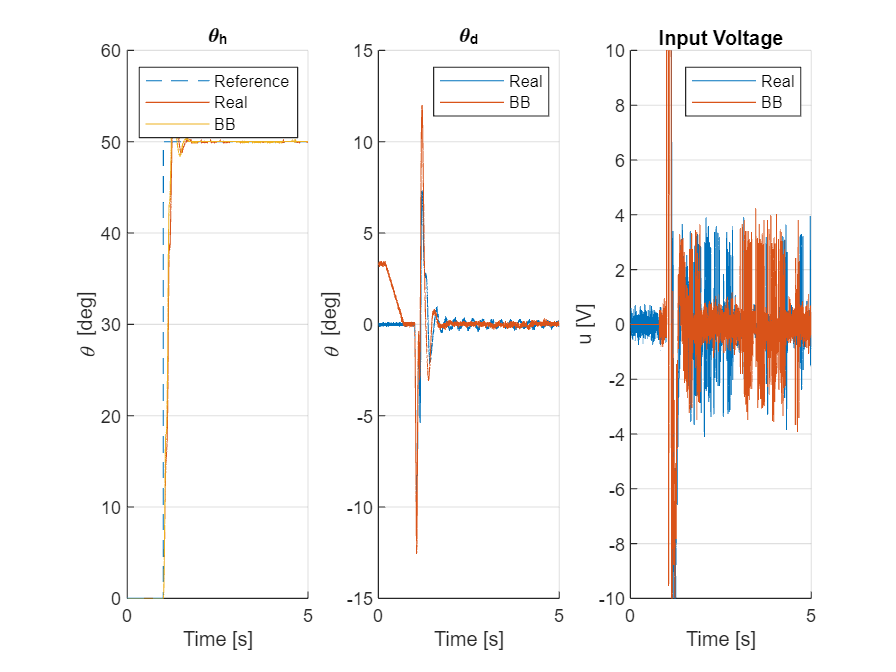

% select pole in position 2 wich is the complex conjugate
lqr_nominal_9.w0 = abs(lqr_nominal_9.polesG(2)); % used before

% definition of necessary parameters
lqr_nominal_9.q22 =[0.01 1 100];
lqr_nominal_9.q22_select = 3; % value used to set q22 takes values in {1 , 2, 3}
lqr_nominal_9.thh_bar = 5*pi/180;
lqr_nominal_9.u_bar = 10;

% definition of necesseray prime matrices
lqr_nominal_9.AQ_prime = [0 1; -lqr_nominal_9.w0^2 0];
lqr_nominal_9.BQ_prime = [0; 1];
lqr_nominal_9.CQ_prime = [sqrt(lqr_nominal_9.q22(lqr_nominal_9.q22_select))*lqr_nominal_9.w0^2 0];
lqr_nominal_9.DQ_prime = 0;

% definition of necesseray Q matrices
lqr_nominal_9.AQ = lqr_nominal_9.AQ_prime;
lqr_nominal_9.BQ = [zeros(2,1) lqr_nominal_9.BQ_prime zeros(2)];
lqr_nominal_9.CQ = [zeros(1,2); lqr_nominal_9.CQ_prime; zeros(2)];
lqr_nominal_9.DQ = diag([1/lqr_nominal_9.thh_bar lqr_nominal_9.DQ_prime 0 0]);

% definition of necesseray A matrices
lqr_nominal_9.AA = [SS.A zeros(4,2); lqr_nominal_9.BQ lqr_nominal_9.AQ];
lqr_nominal_9.BA = [SS.B; zeros(2,1)];
lqr_nominal_9.CA = [SS.C zeros(1,2)];
lqr_nominal_9.DA = 0;
lqr_nominal_9.QA = [lqr_nominal_9.DQ'*lqr_nominal_9.DQ          lqr_nominal_9.DQ'*lqr_nominal_9.CQ ;
                    lqr_nominal_9.CQ'*lqr_nominal_9.DQ          lqr_nominal_9.CQ'*lqr_nominal_9.CQ ];
lqr_nominal_9.RA = 1/lqr_nominal_9.u_bar^2;
lqr_nominal_9.K = lqr(lqr_nominal_9.AA, lqr_nominal_9.BA, lqr_nominal_9.QA, lqr_nominal_9.RA);

lqr_nominal_9.N = [lqr_nominal_9.AA lqr_nominal_9.BA; lqr_nominal_9.CA lqr_nominal_9.DA]\[zeros(6,1); 1];
lqr_nominal_9.Nx = lqr_nominal_9.N(1:6);
lqr_nominal_9.Nu = lqr_nominal_9.N(7);


%this part has been added to use only a simulation file for multiple tests
ss_lqr.Ki =  0;
ss_lqr.K =  lqr_nominal_9.K;
ss_lqr.Nx = lqr_nominal_9.Nx;
ss_lqr.Nu = lqr_nominal_9.Nu;
ss_lqr.AQ = lqr_nominal_9.AQ;
ss_lqr.BQ = lqr_nominal_9.BQ;
ss_lqr.I = eye(2);
ss_lqr.zero = zeros(2,4);


lqr_nominal_9.real_model = sim('LQR_Real','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
lqr_nominal_9.BB = sim('LQR_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');



figure
subplot(1,3,1);
hold on;
plot(lqr_nominal_9.real_model.thh_ref.time, lqr_nominal_9.real_model.thh_ref.signals.values,'--');
plot(lqr_nominal_9.real_model.thh_meas.time, lqr_nominal_9.real_model.thh_meas.signals.values);
plot(lqr_nominal_9.BB.thh_est.time, lqr_nominal_9.BB.thh_est.signals.values);
legend('Reference', 'Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_nominal_9.real_model.thd_meas.time, lqr_nominal_9.real_model.thd_meas.signals.values);
plot(lqr_nominal_9.BB.thd_est.time, lqr_nominal_9.BB.thd_est.signals.values);
legend('Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_nominal_9.real_model.u.time, lqr_nominal_9.real_model.u.signals.values);
plot(lqr_nominal_9.BB.u.time, lqr_nominal_9.BB.u.signals.values);
legend('Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

stepinfo(lqr_nominal_9.real_model.thh_meas.signals.values, lqr_nominal_9.real_model.thh_meas.time, simul.stepdeg, 'SettlingTimeThreshold', 0.05, 'RiseTimeLimits', [0.001, 0.95])

ans = struct with fields:
         RiseTime: 0.2227
    TransientTime: 1.3663
     SettlingTime: 1.3663
      SettlingMin: 47.5200
      SettlingMax: 55.0800
        Overshoot: 10.1600
       Undershoot: 0
             Peak: 55.0800
         PeakTime: 1.2870


#### LQR Robust point 11

#### we will need to test different values of q22

lqr_robust_11.sysG = ss(SS.A, SS.B, SS.C, SS.D);
%finding the angular frequency w0 of the pair of complex conjugate eigs
%The angular frequency of a complex conjugate pair p = a +/- ib is
%w0 = sqrt(a^2 + b^2) = abs(p)
lqr_robust_11.polesG = pole(lqr_robust_11.sysG);
% look at the position of the poles then select the right ones
disp(lqr_robust_11.polesG)

   0.0000 + 0.0000i
  -2.1807 +41.2141i
  -2.1807 -41.2141i
  -3.4946 + 0.0000i



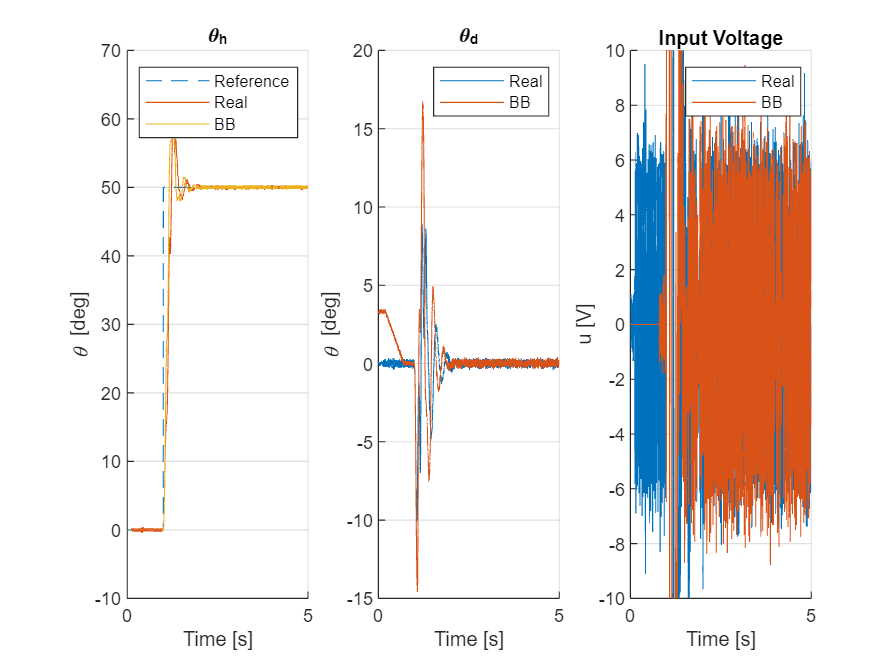

% select pole in position 2 wich is the complex conjugate
lqr_robust_11.w0 = abs(lqr_robust_11.polesG(2));

% definition of necessary parameters
lqr_robust_11.q22 =[0.01 1 100 200];
lqr_robust_11.q22_select = 4; % value used to set q22 takes values in {1, 2, 3}
lqr_robust_11.qI = 0.01; %needs to be tuned for every q22 good values are [0.01, 0.01,
lqr_robust_11.thh_bar = 0.03;%5*pi/180;
lqr_robust_11.u_bar = 10;

% definition of necesseray prime matrices
lqr_robust_11.AQ_prime = [0 1; -lqr_robust_11.w0^2 0];
lqr_robust_11.BQ_prime = [0; 1];
lqr_robust_11.CQ_prime = [sqrt(lqr_robust_11.q22(lqr_robust_11.q22_select))*lqr_robust_11.w0^2 0];
lqr_robust_11.DQ_prime = 0;

% definition of necesseray Q matrices
lqr_robust_11.AQ = lqr_robust_11.AQ_prime;
lqr_robust_11.BQ = [zeros(2,1) lqr_robust_11.BQ_prime zeros(2)];
lqr_robust_11.CQ = [zeros(1,2); lqr_robust_11.CQ_prime; zeros(2)];
lqr_robust_11.DQ = diag([1/lqr_robust_11.thh_bar lqr_robust_11.DQ_prime 0 0]);

% definition of necesseray A matrices
lqr_robust_11.AA = [SS.A zeros(4,2); lqr_robust_11.BQ lqr_robust_11.AQ];
lqr_robust_11.BA = [SS.B; zeros(2,1)];
lqr_robust_11.CA = [SS.C zeros(1,2)];
lqr_robust_11.DA = 0;
lqr_robust_11.QA = [lqr_robust_11.DQ'*lqr_robust_11.DQ          lqr_robust_11.DQ'*lqr_robust_11.CQ ;
                    lqr_robust_11.CQ'*lqr_robust_11.DQ          lqr_robust_11.CQ'*lqr_robust_11.CQ ];

% definition of necesseray extended matrices
lqr_robust_11.Ae = [0 lqr_robust_11.CA; zeros(6,1) lqr_robust_11.AA];
lqr_robust_11.Be = [0; lqr_robust_11.BA];
lqr_robust_11.Ce = [0 lqr_robust_11.CA];
lqr_robust_11.De = 0;
lqr_robust_11.Qe = [lqr_robust_11.qI        zeros(1,6);
                    zeros(6,1)              lqr_robust_11.QA];
lqr_robust_11.Re = 1/lqr_robust_11.u_bar^2;


lqr_robust_11.Ke = lqr(lqr_robust_11.Ae, lqr_robust_11.Be, lqr_robust_11.Qe, lqr_robust_11.Re);
lqr_robust_11.Ki = lqr_robust_11.Ke(1);
lqr_robust_11.K = lqr_robust_11.Ke(2:7);

lqr_robust_11.N = [lqr_robust_11.AA lqr_robust_11.BA; lqr_robust_11.CA lqr_robust_11.DA]\[zeros(6,1); 1];
lqr_robust_11.Nx = lqr_robust_11.N(1:6);
lqr_robust_11.Nu = lqr_robust_11.N(7);


%this part has been added to use only a simulation file for multiple tests
ss_lqr.Ki =  lqr_robust_11.Ki;
ss_lqr.K =  lqr_robust_11.K;
ss_lqr.Nx = lqr_robust_11.Nx;
ss_lqr.Nu = lqr_robust_11.Nu;
ss_lqr.AQ = lqr_robust_11.AQ;
ss_lqr.BQ = lqr_robust_11.BQ;
ss_lqr.I = eye(2);
ss_lqr.zero = zeros(2,4);


lqr_robust_11.real_model = sim('LQR_Real','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
lqr_robust_11.BB = sim('LQR_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');



figure
subplot(1,3,1);
hold on;
plot(lqr_robust_11.real_model.thh_ref.time, lqr_robust_11.real_model.thh_ref.signals.values,'--');
plot(lqr_robust_11.real_model.thh_meas.time, lqr_robust_11.real_model.thh_meas.signals.values);
plot(lqr_robust_11.BB.thh_est.time, lqr_robust_11.BB.thh_est.signals.values);
legend('Reference', 'Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,3,2);
hold on;
plot(lqr_robust_11.real_model.thd_meas.time, lqr_robust_11.real_model.thd_meas.signals.values);
plot(lqr_robust_11.BB.thd_est.time, lqr_robust_11.BB.thd_est.signals.values);
legend('Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')
subplot(1,3,3);
hold on;
plot(lqr_robust_11.real_model.u.time, lqr_robust_11.real_model.u.signals.values);
plot(lqr_robust_11.BB.u.time, lqr_robust_11.BB.u.signals.values);
legend('Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')

stepinfo(lqr_robust_11.real_model.thh_meas.signals.values, lqr_robust_11.real_model.thh_meas.time, simul.stepdeg, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1831
    TransientTime: 1.3912
     SettlingTime: 1.3913
      SettlingMin: 45.3600
      SettlingMax: 60.3000
        Overshoot: 20.6000
       Undershoot: 0.7200
             Peak: 60.3000
         PeakTime: 1.2700


### Challenge

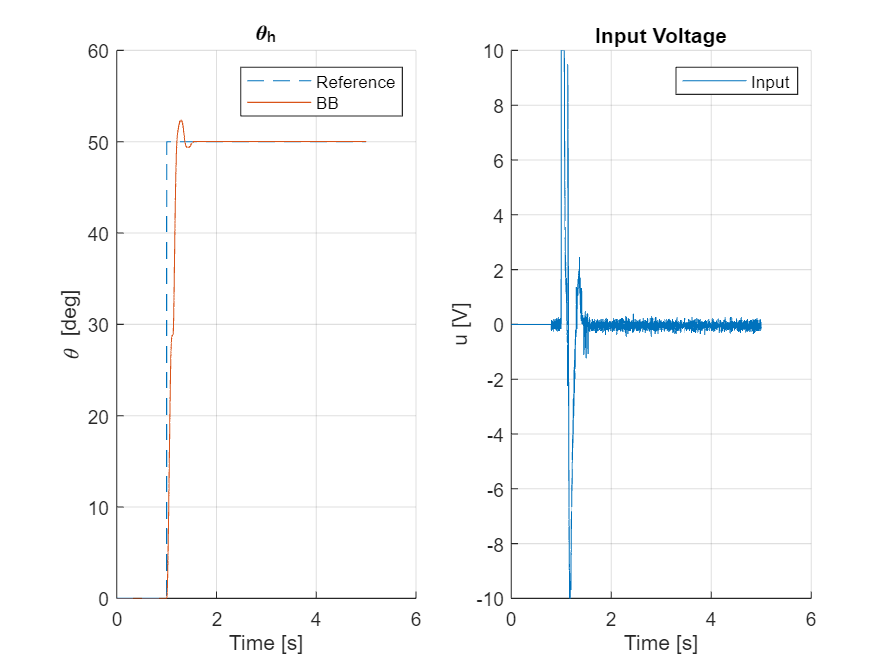

challenge.uinterval = 0; % 0.1314 - minimum time from 0.01 to 0.95
challenge.refAmp = 11;      % sym. rlocus: 11,   freq. dep.: 10
challenge.tinterval = 0.13; % sym. rlocus: 0.13, freq. dep.: 0.2

%% Two switch between freq. dep. and sym. rlocus design, need to change controller in simulink model

% Nominal design using root locus (leaving r=0.00027 gives best results, ts=189ms)
ss_nominal.K = lqr_nominal.K;
ss_nominal.Nx = lqr_nominal.Nx;
ss_nominal.Nu = lqr_nominal.Nu;

% Nominal desing using frequency dependent cost (sym. rlocus gives better performance, ts=230ms)
ss_lqr.Ki =  0;
ss_lqr.K =  lqr_nominal_9.K;
ss_lqr.Nx = lqr_nominal_9.Nx;
ss_lqr.Nu = lqr_nominal_9.Nu;
ss_lqr.AQ = lqr_nominal_9.AQ;
ss_lqr.BQ = lqr_nominal_9.BQ;
ss_lqr.I = eye(2);
ss_lqr.zero = zeros(2,4);


challenge.data = sim('Challenge','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure
subplot(1,2,1);
hold on;
plot(challenge.data.thh_ref.time, challenge.data.thh_ref.signals.values,'--');
plot(challenge.data.thh_est.time, challenge.data.thh_est.signals.values);
legend('Reference', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(challenge.data.u.time, challenge.data.u.signals.values);
legend('Input')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input Voltage')


stepinfo(challenge.data.thh_est.signals.values, challenge.data.thh_est.time, simul.stepdeg, 'SettlingTimeThreshold', 0.05, 'RiseTimeLimits', [0.001, 0.95])

ans = struct with fields:
         RiseTime: 0.1846
    TransientTime: 1.1889
     SettlingTime: 1.1889
      SettlingMin: 47.5200
      SettlingMax: 52.3800
        Overshoot: 4.7600
       Undershoot: 0
             Peak: 52.3800
         PeakTime: 1.2720
